# Element to Mineral Inversion

Mustafa Al Ibrahim (Mustafa.Geoscientist@outlook.com)

## User Defined Parameters

clear all;
mineralToUse = {'Calcite', 'Quartz', 'Pyrite', 'Illite1', 'Illite3', 'Plagioclase'};
mineralToUse = {'Calcite', 'Quartz', 'Illite2'};
elementsToUse = {'Ca', 'Si', 'Al', 'Fe', 'S', 'P', 'K', 'Mg'};
dataFileName = 'D:\Users\malibrah\OneDrive\Stanford\Project Cella\Data\Alcor-1\XRF_Clean.xlsx';
dataFileName = 'Data.csv';


## Running the Algorithem

% Load the chemical constants file and analyze defined minerals
[Elements, Minerals] = LoadChemicalConstants('Elements.csv', 'Minerals.csv');
% Load and prepare the data
data = readtable(dataFileName, 'ReadRowNames',true);
data = FilterData(data,elementsToUse);

% Build the A matrix
Minerals = AnalyzeMinerals(Elements, Minerals);
[Aprime, AprimeTable] = ConstructAprimeMatrix(Minerals, elementsToUse, mineralToUse);

% Show the A table for confirmation
AprimeTable

AprimeTable = 8×3 table
          Calcite    Quartz     Illite2
          _______    _______    _______

    Ca    0.40043          0          0
    Si          0    0.46743    0.29309
    Al          0          0    0.14078
    Fe          0          0          0
    S           0          0          0
    P           0          0          0
    K           0          0          0
    Mg          0          0          0



% Invert
[results, resultsTable] = InvertToMinerals(Aprime, data, mineralToUse);

% Show the results table
resultsTable

resultsTable = 4×3 table
         Calcite    Quartz    Illite2
         _______    ______    _______

    1    35.613     45.945    18.442 
    2    68.199     25.718    6.0835 
    4    48.892      48.53     2.578 
    5    61.637     24.333     14.03 


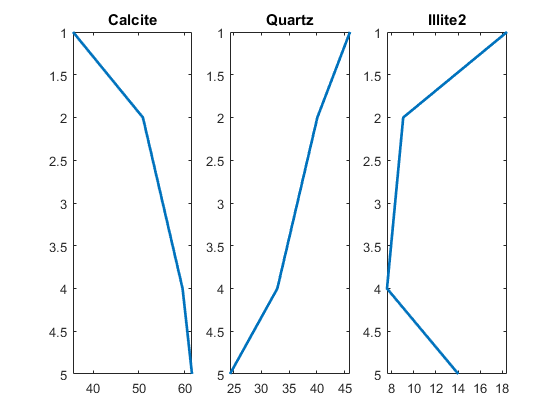


%% Plot Results
PlotResultsTable(resultsTable,10)


%% Carb File
carbFile = 'D:\Users\malibrah\OneDrive\Stanford\Project Cella\Data\Alcor-1\Carb.xlsx';
carbData = xlsread(carbFile);

Error using xlsread (line 139)
XLSREAD unable to open file 'D:\Users\malibrah\OneDrive\Stanford\Project Cella\Data\Alcor-1\Carb.xlsx'.
File 'D:\Users\malibrah\OneDrive\Stanford\Project Cella\Data\Alcor-1\Carb.xlsx' not found.

subplot(1, numel(mineralToUse), 1); hold on;
scatter(carbData(:,3), carbData(:,1), '.');



## References

De Caritat, P., Bloch, J., and Hutcheon, I, 1994, LPNORM: A linear programming normative analysis code: Computer and Geosciences, v. 20, no. 3, p. 313-347.